# Utilities for Poisson-noise matched filter

# in the astronomy & astrophysics toolbox for MATLAB

## Description:

**Convention:**

We note that our convention is not to renormalize $P_{\rm poi}$ to unity, and to subtract the background expectation value from the image prior to filtering. Other conventions are valid as long as they are applied consistently.

## Low level functions:

**Calculating the flux threshold:**

The function `ImUtil.X.poiss_f_threshold `can be used to calculate the flux threshold $f_{th}$and $S_{th}$using simulations. The input for this function is the background level (in counts), a stamp of the PSF or a scalar specifying the sigma of a Gaussian PSF (pixels), and the false alarm probability. The user can control the number of simulations, anc convergence accuracy (see help `AstroIm.poiss_f_threshold` for more information).

Example:

[Flim,Slim]=ImUtil.X.poiss_f_threshold(0.005,2,0.001)

Flim =        2.7792


Slim =        6.5501


**Generating the Poisson-noise matched filter:**

In order to generate a Poisson-noise matched filter you can use the @Kernel2 static class:

K=Kernel2.pmf

K =     0.0006341    0.0046759     0.021962     0.065276      0.12344      0.15193      0.12344     0.065276     0.021962    0.0046759    0.0006341
    0.0046759     0.034045      0.15193      0.40441      0.67843      0.79406      0.67843      0.40441      0.15193     0.034045    0.0046759
     0.021962      0.15193      0.57512       1.2123       1.7226       1.9086       1.7226       1.2123      0.57512      0.15193     0.021962
     0.065276      0.40441       1.2123       2.1009       2.7061        2.915       2.7061       2.1009       1.2123      0.40441     0.065276
      0.12344      0.67843       1.7226       2.7061       3.3398       3.5549       3.3398       2.7061       1.7226      0.67843      0.12344
      0.15193      0.79406       1.9086        2.915       3.5549       3.7714       3.5549        2.915       1.9086      0.79406      0.15193
      0.12344      0.67843       1.7226       2.7061       3.3398       3.5549       3.3398       2.7061       1.7226      0.67843  

surface(K)
% or
K=Kernel2.pmf(0.005,Kernel2.gauss,5)

K =     0.0010566    0.0077811      0.03634      0.10654        0.198      0.24174        0.198      0.10654      0.03634    0.0077811    0.0010566
    0.0077811     0.056115      0.24174      0.60469       0.9624       1.1055       0.9624      0.60469      0.24174     0.056115    0.0077811
      0.03634      0.24174      0.83098       1.5965       2.1593       2.3583       2.1593       1.5965      0.83098      0.24174      0.03634
      0.10654      0.60469       1.5965       2.5615       3.1899       3.4039       3.1899       2.5615       1.5965      0.60469      0.10654
        0.198       0.9624       2.1593       3.1899       3.8363       4.0542       3.8363       3.1899       2.1593       0.9624        0.198
      0.24174       1.1055       2.3583       3.4039       4.0542        4.273       4.0542       3.4039       2.3583       1.1055      0.24174
        0.198       0.9624       2.1593       3.1899       3.8363       4.0542       3.8363       3.1899       2.1593       0.9624  

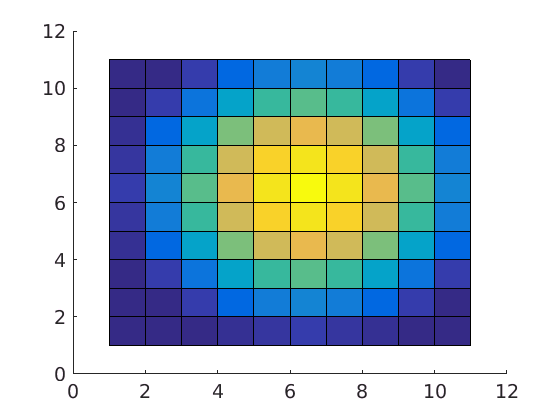

surface(K)

**Filtering**

You can filter an image using the built-in function filter2. However, a more convinient tool is the SIM/filter function that works on SIM objects and can filter an image using a several methods.

% generate a random poisson noise SIM image
Back = 0.005;
Im = SIM

Im =   SIM with properties:

               Im: []
    ImageFileName: ''
           BackIm: []
            ErrIm: []
         WeightIm: []
              Cat: []
              Col: []
          ColCell: []
         ColUnits: []
         SortedBy: []
      SortedByCol: []
             Name: []
           Source: []
        Reference: []
          Version: []
           Header: {0×3 cell}
              WCS: []
         UserData: []
             Mask: []
          MaskDic: []
              PSF: []
           ErrPSF: []
           ParPSF: {}
           CooPSF: []


Im.Im = poissrnd(ones(1024,1024).*Back);
K=Kernel2.pmf(Back,1.5,3);
FiltIm = filter(Im,K);

Background estimation

## High level functions

**Running mextractor**

The matched filter source extraction mextractor can use the Poisson-noise filter.

However, this...

Back = 0.005;
Im = SIM

Im =   SIM with properties:

               Im: []
    ImageFileName: ''
           BackIm: []
            ErrIm: []
         WeightIm: []
              Cat: []
              Col: []
          ColCell: []
         ColUnits: []
         SortedBy: []
      SortedByCol: []
             Name: []
           Source: []
        Reference: []
          Version: []
           Header: {0×3 cell}
              WCS: []
         UserData: []
             Mask: []
          MaskDic: []
              PSF: []
           ErrPSF: []
           ParPSF: {}
           CooPSF: []


Im.Im = poissrnd(ones(1024,1024).*Back);

[Flim,Slim,Status]=ImUtil.X.poiss_f_threshold(Back,1.5,1e-3);
PMF   = Kernel2.pmf(Back,1.5,Flim);
Im.PSF = PMF;
%Im = mextractor(Im, 'ThreshIsSigma',false,'FilterFind',false,'Filter',PMF,'Thresh',Flim)

## Example on Chandra images

% Build a local copy of the Chandra observations catalog
% may take many hours:
% VO.Chandra.build_obsid_cat

% Copy Chandra observations to local directory
% VO.Chandra.wget_obsid(366);
% Read ACIS observations
% [Cat,GT] = AstroX.read_chandra_acis('/raid/eran/projects/Algorithms/PoissonMatchedFilter/Chandra/ObsID366/');

cd /raid/eran/projects/Algorithms/PoissonMatchedFilter/Chandra/ChandraDeep/
T   = FITS.read_table('acismCDFS_2000-2007-2010N002_evt2.fits');

PMF = Kernel2.pmf(Back,1.5,Flim);

